# MAIN_SIM_3D_ALL_GRAPH: Visualize the results obtained by the script MAIN_SIM_3D_ALL_PROC

This script generates graphs from results obtaind by  MAIN_SIM_3D_ALL_PROC. 

The results are load from

-  ../results/sim_clg_yyyy-MM-dd-HH-mm-lv-#-slope-#-dfreq-#.mat

- ../results/sim_results_dd-MM-yyy-HH-mm.mat

Requirements: MATLAB R2022a

Copyright (c) 2022, Ruiki KOBAYASHI and Shogo MURAMATSU, All rights reserved.

Contact address: Shogo MURAMATSU,

    Faculty of Engineering, Niigata University,

    8050 2-no-cho Ikarashi, Nishi-ku,

    Niigata, 950-2181, JAPAN

    [http://msiplab.eng.niigata-u.ac.jp/](http://msiplab.eng.niigata-u.ac.jp/)

% Filenames
dtclg = "2022-04-14-17-08";
dtres = "2022-04-14-19-41";
 
%
if ~exist("+support/vol3d.m","file")
    unzip("https://jp.mathworks.com/matlabcentral/mlc-downloads/downloads/submissions/22940/versions/5/download/zip")
    movefile("./vol3d.m","./+support/")
end

agamma = 1.7;
rsgamma = 0.25;
vsgamma = 0.25;

## Coherence funciton

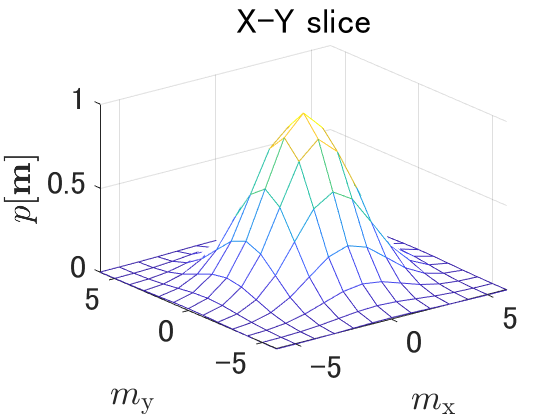

% Parameters
Scale = 1; 
Sigmaxy = 2;
Sigmaz = 30;
Freq  = 3e-1;
B4Sinc = 5e-2;
% Definition
pxy = @(mx,my) exp(-(mx.^2+my.^2)./(2*Sigmaxy.^2));
pz = @(mz) exp(-(mz.^2/(2*Sigmaz.^2))).*cos(2*pi*Freq.*mz).*sinc(B4Sinc*mz);
pxyz = @(mx,my,mz) Scale*pxy(mx,my).*pz(mz);
% Sample points
z = -37:37;
lenz = length(z);
xy = -6:6;
lenxy = length(xy);
[X,Y,Z] = meshgrid(-6:6,-6:6,z);
p = pxyz(X,Y,Z);
% X-Y slice
hfig = figure;
hmeshxy = mesh(X(:,:,ceil(lenxy/2)),Y(:,:,ceil(lenxy/2)),p(:,:,ceil(lenz/2)));
title("X-Y slice")
xlabel("$m_\mathrm{x}$","Interpreter","latex")
ylabel("$m_\mathrm{y}$","Interpreter","latex")
zlabel("$p[\mathbf{m}]$","Interpreter","latex")
ax = hmeshxy.Parent;
ax.FontSize = 24;
ax.XTick = [-5 0 5];
ax.YTick = [-5 0 5];
ax.ZTick = [0 0.5 1];
exportgraphics(ax,"../results/fig2arev.png","Resolution",300);

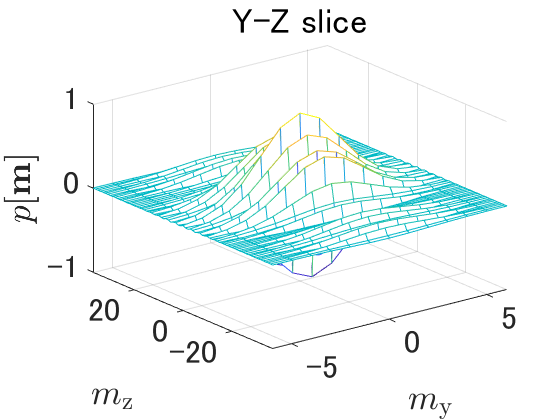

close(hfig)
% Y-Z sline
hfig = figure;
hmeshz = mesh(squeeze(Y(:,ceil(lenxy/2),:)),squeeze(Z(:,ceil(lenxy/2),:)),squeeze(p(:,ceil(lenxy/2),:)));
title("Y-Z slice")
xlabel("$m_\mathrm{y}$","Interpreter","latex")
ylabel("$m_\mathrm{z}$","Interpreter","latex")
zlabel("$p[\mathbf{m}]$","Interpreter","latex")
ax = hmeshz.Parent;
ax.FontSize = 24;
ax.XTick = [-5 0 5];
ax.YTick = [-20 0 20];
ax.ZTick = [-1 0 1];
ax.YLim = [-37 37];
exportgraphics(ax,"../results/fig2brev.png","Resolution",300);

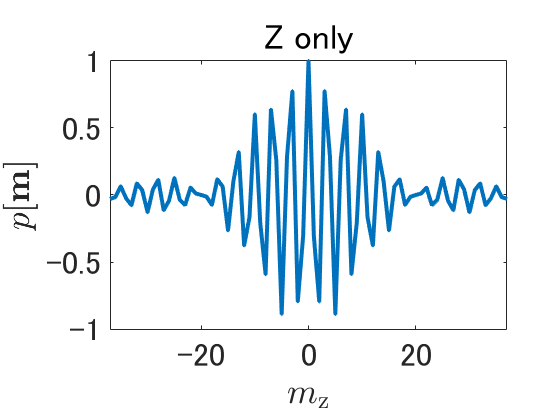

close(hfig)
% Z only
hfig = figure;
hpltz = plot(z,squeeze(p(ceil(lenxy/2),ceil(lenxy/2),:)));
title("Z only")
xlabel("$m_\mathrm{z}$","Interpreter","latex")
ylabel("$p[\mathbf{m}]$","Interpreter","latex")
hpltz.LineWidth = 3;
ax = hpltz.Parent;
ax.FontSize = 24;
ax.XTick = [-20 0 20];
ax.YTick = [-1 -0.5 0 0.5 1];
ax.XLim = [-37 37];
ax.YLim = [-1 1];
ax.DataAspectRatio = [25 1 1];
exportgraphics(ax,"../results/fig2crev.png","Resolution",300);

close(hfig)

## Load simulation configurations

targetdir = "../data/materials/sim_results_" + dtres;
cfilename = targetdir + "/tables";
disp(cfilename)

../data/materials/sim_results_2022-04-14-19-41/tables


S = load(cfilename,"tbEvals","tbSimConfs");
tbEvals = S.tbEvals;
tbSimConfs = S.tbSimConfs;

## Simulation results of artificial opaque-tape data 

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-0.5"

tape_sim041.mat 


    slope    depthFreq    sigmaw    iTrial
    _____    _________    ______    ______

      0         0.5        0.05       1   



Simulation ID: 41


../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-0.5/tape_sim041.mat 


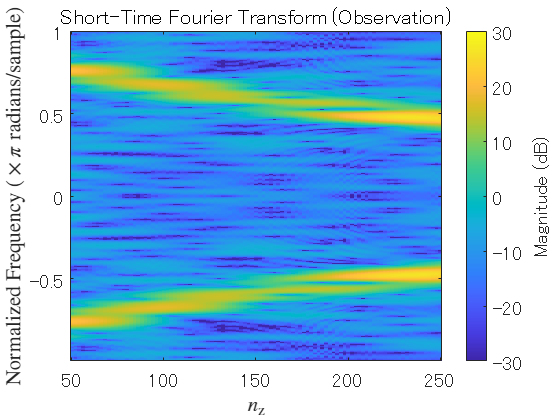

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-2"

tape_sim026.mat 


    slope    depthFreq    sigmaw    iTrial
    _____    _________    ______    ______

      0          2         0.05       1   



Simulation ID: 26


../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-2/tape_sim026.mat 


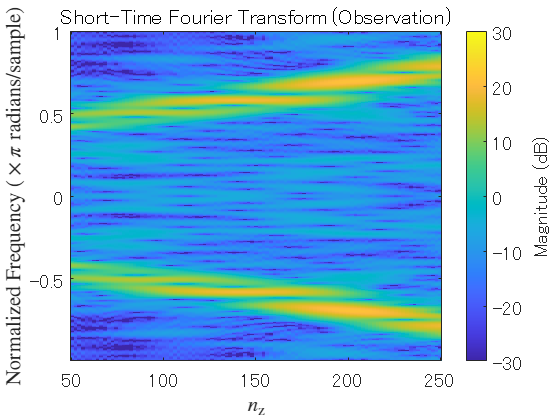

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-3"

tape_sim011.mat 


    slope    depthFreq    sigmaw    iTrial
    _____    _________    ______    ______

      0          3         0.05       1   



Simulation ID: 11


../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-3/tape_sim011.mat 


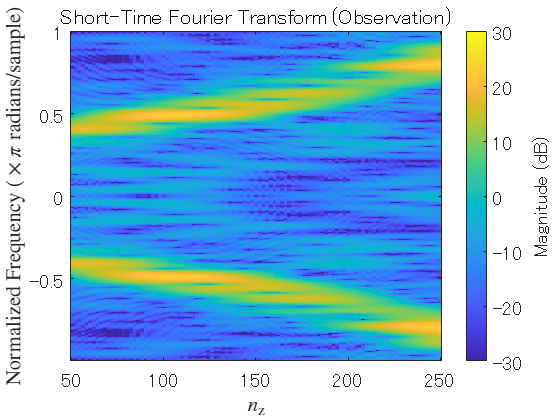

sigmaw = 0.05;
slope = 0;
depthfactor = [0.5 2 3];

%
tfigname = @(x) "../results/fig8"+string(char(96+x))+"rev.png";

%
len = 100;
config_.win = hamming(len,'periodic');
config_.len = len;
config_.div = 150;
isubfig = 1;
for depthFreq = depthfactor
    targetdir = "../data/materials/sim_clg_" +dtclg...
        +"-sgmw-"+num2str(sigmaw)...
        +"-slope-"+num2str(slope)...
        +"-dfreq-"+num2str(depthFreq)
    targetfiles = string(ls(targetdir));
    if length(targetfiles)==1
        targetfiles = split(targetfiles);
    end
    tfilename = targetfiles(contains(targetfiles,'tape_sim'));
    disp(tfilename)
    
    % Simulation configulation
    simId = str2double(extractBetween(tfilename,'tape_sim','.mat'));
    simConfig = tbSimConfs{simId};
    disp(simConfig)

    % Opquie-tape simulation results
    disp("Simulation ID: " + simId)
    targetfile = targetdir+"/"+tfilename;
    disp(targetfile)
    S = load(targetfile,'tEst','tdObs','tObs');
    tEst = S.tEst;
    tdObs = S.tdObs;
    tObs = S.tObs;
  
    % Observation
    hfig = figure;
    config_.obsz = size(tdObs,3);
    fcn_stftview_(hfig,tdObs,'Observation',config_)
    exportgraphics(hfig,tfigname(isubfig),"Resolution",300);
    isubfig =isubfig+1;

    % Estimation
    hfig = figure;
    config_.obsz = size(tEst,3);
    fcn_stftview_(hfig,tEst,'Estimation',config_)
    exportgraphics(hfig,tfigname(isubfig),"Resolution",300);
    isubfig =isubfig+1;
    close(hfig)
end

## Simulation results of artificial glass data 

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-2"

    slope    depthFreq    sigmaw    iTrial
    _____    _________    ______    ______

      0          2         0.05       1   



Simulation ID: 26


../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0-dfreq-2/glass_sim026.mat


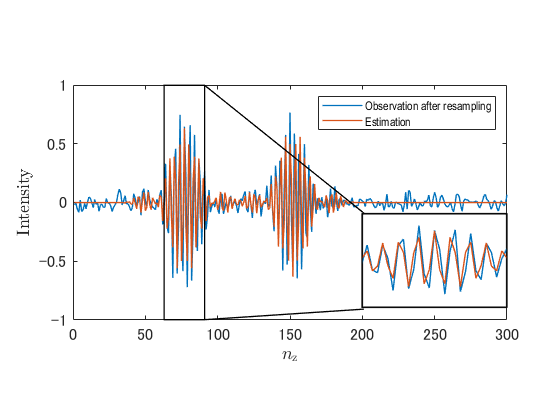

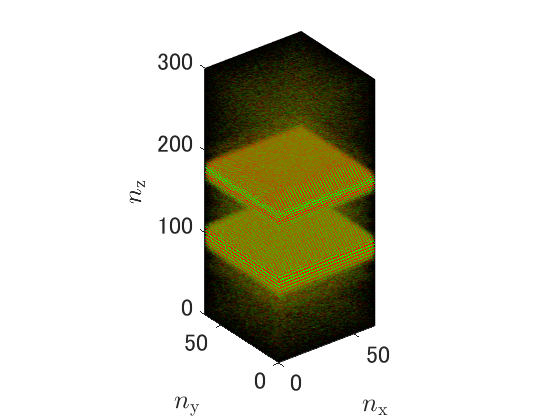

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0.25-dfreq-2"

    slope    depthFreq    sigmaw    iTrial
    _____    _________    ______    ______

    0.25         2         0.05       1   



Simulation ID: 21


../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0.25-dfreq-2/glass_sim021.mat


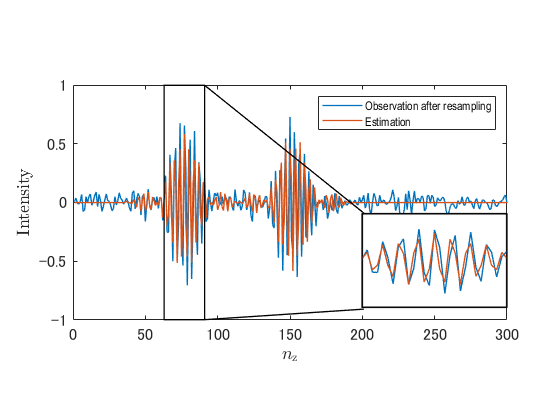

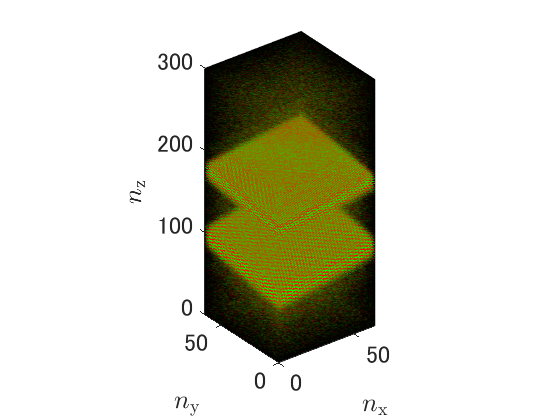

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0.5-dfreq-2"

    slope    depthFreq    sigmaw    iTrial
    _____    _________    ______    ______

     0.5         2         0.05       1   



Simulation ID: 16


../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0.5-dfreq-2/glass_sim016.mat


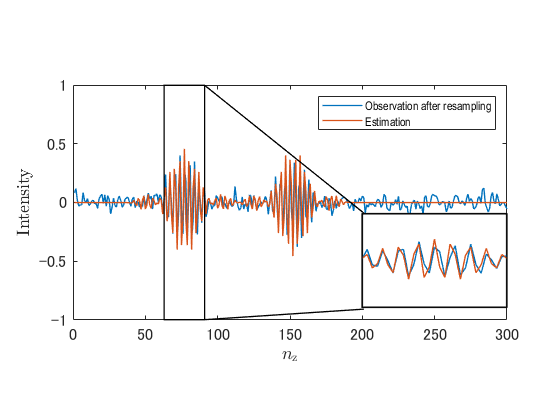

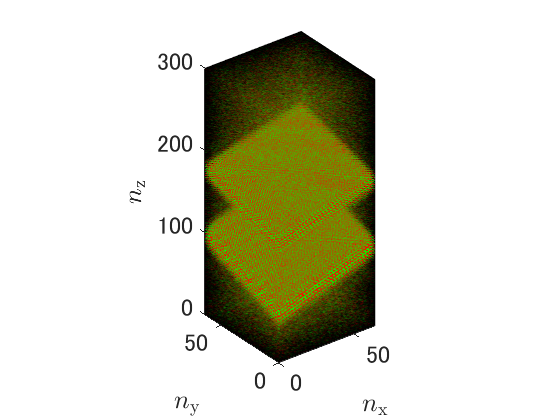

sigmaw = 0.05;
slopefactor = [0 0.25 0.5];
dfreq = 2;

%
gfigname = @(x) "../results/fig9"+string(char(96+x))+"rev.png";

isubfig = 1;
for slope = slopefactor
    targetdir = "../data/materials/sim_clg_" +dtclg...
        +"-sgmw-"+num2str(sigmaw)...
        +"-slope-"+num2str(slope)...
        +"-dfreq-"+num2str(dfreq)
    targetfiles = string(ls(targetdir));
    if length(targetfiles)==1
        targetfiles = split(targetfiles);
    end
    gfilename = targetfiles(contains(targetfiles,'glass_sim'));
    
    % Simulation configulation
    simId = str2double(extractBetween(gfilename,'glass_sim','.mat'));
    simConfig = tbSimConfs{simId};
    disp(simConfig)

    % Glass simulation results
    disp("Simulation ID: " + simId)
    targetfile = targetdir+"/"+gfilename;
    disp(targetfile)
    S = load(targetfile,'gsaEst','gsaObs','gsbObs'); 
    gsaEst = S.gsaEst;
    gsaObs = S.gsaObs;
    gsbObs = S.gsbObs; 
  
    % Wave estimation
    hfig = figure;
    fcn_waveview_(hfig,gsaObs,gsaEst,...
        ["Observation after resampling","Estimation"],...
        "Intensity");
    exportgraphics(hfig,gfigname(isubfig),"Resolution",300);
    isubfig =isubfig+1;
    close(hfig)

    % Observation
    hfig = figure;
    voldata = gsbObs;
    fcn_volviewer_(hfig,voldata,agamma);
    exportgraphics(hfig,gfigname(isubfig),"Resolution",300);
    isubfig = isubfig+1;    
    close(hfig)
end

## Simulation results of restoration 

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.03-slope-0.25-dfreq-2"

../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.03-slope-0.25-dfreq-2/rest_sim023.mat 


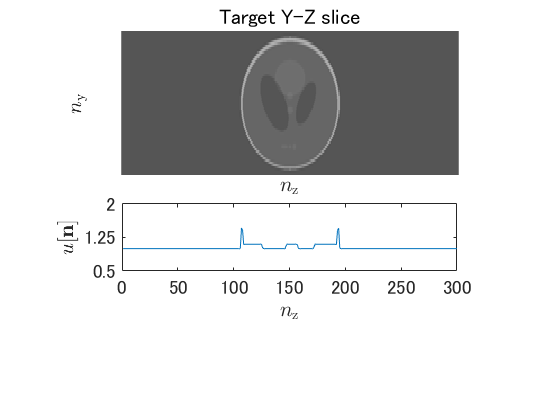

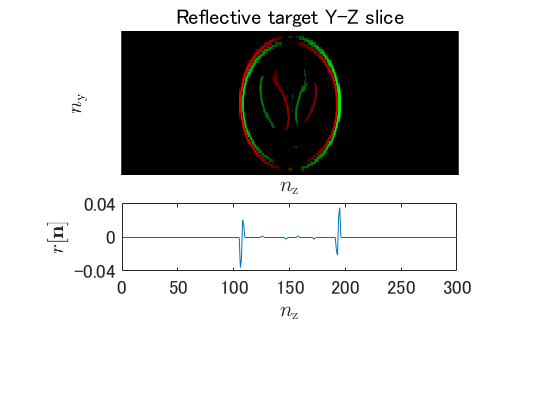

     method     barlambda     bareta      lambda        eta       gamma1      phiMode       vrange              msrProc                                     fwdDic                                                   adjDic                                                   gdnFcnG                            paramDev    pScale    pSigmaz    pB4Sinc    pFreq    pSigamxy    sigmaw
    ________    _________    ________    _________    ________    _______    __________    ________    _________________________    ______________________________________________________    _____________________________________________________    ______________________________________________________    ________    ______    _______    _______    _____    ________    ______

    {'udht'}    0.0025119    0.012619    0.0025119    0.012619    0.57154    {'Linear'}    1    1.5    {1×1 support.Coherence3d}    {1×1 saivdr.dictionary.udhaar.UdHaarSynthesis3dSystem}    {1×1 saivdr.dictionary.udhaar.UdHaarAnalysis3dSystem}  

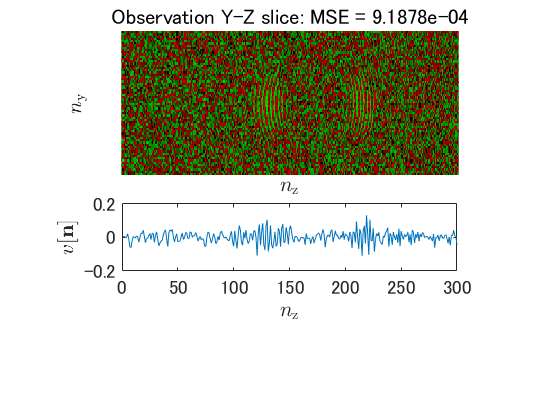

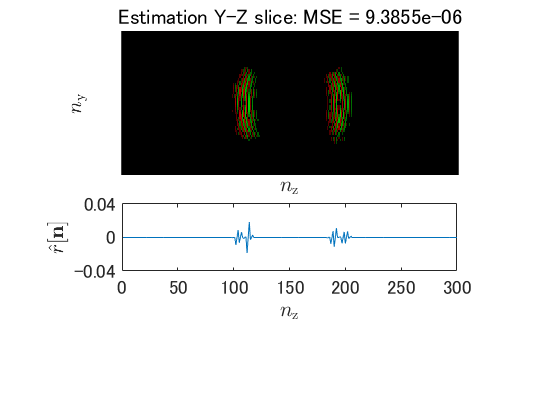

targetdir = "../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0.25-dfreq-2"

../data/materials/sim_clg_2022-04-14-17-08-sgmw-0.05-slope-0.25-dfreq-2/rest_sim021.mat 


     method     barlambda     bareta      lambda        eta       gamma1      phiMode       vrange              msrProc                                     fwdDic                                                   adjDic                                                   gdnFcnG                            paramDev    pScale    pSigmaz    pB4Sinc    pFreq    pSigamxy    sigmaw
    ________    _________    ________    _________    ________    _______    __________    ________    _________________________    ______________________________________________________    _____________________________________________________    ______________________________________________________    ________    ______    _______    _______    _____    ________    ______

    {'udht'}    0.0025119    0.012619    0.0025119    0.012619    0.59232    {'Linear'}    1    1.5    {1×1 support.Coherence3d}    {1×1 saivdr.dictionary.udhaar.UdHaarSynthesis3dSystem}    {1×1 saivdr.dictionary.udhaar.UdHaarAnalysis3dSystem}  

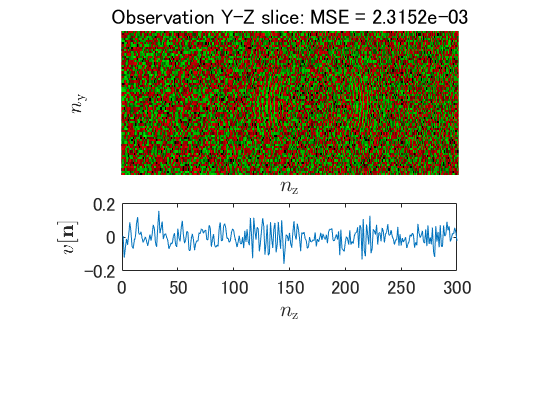

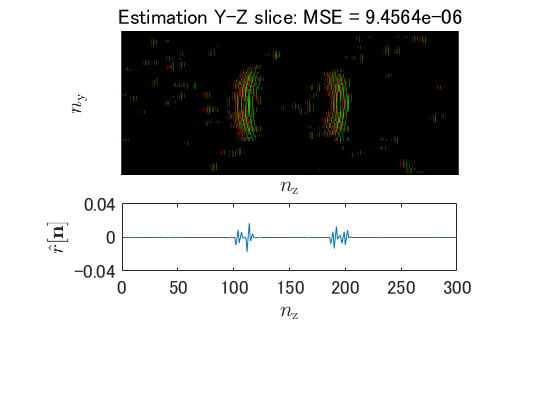

sigmawSet = [0.03 0.05];
slope = 0.25;
dfreq = 2;
%
rScale = 0.04;
vScale = 0.2;
%
rfigname = @(x) "../results/fig11"+string(char(96+x))+"rev.png";
mymse = @(x,y) (norm(x(:)-y(:)).^2)/numel(x);
isubfig = 1;
for sigmaw = sigmawSet
    targetdir = "../data/materials/sim_clg_" +dtclg...
        +"-sgmw-"+num2str(sigmaw)...
        +"-slope-"+num2str(slope)...
        +"-dfreq-"+num2str(dfreq)
    targetfiles = string(ls(targetdir));
    rfilename = targetfiles(contains(targetfiles,'rest_sim'));
    targetfile = targetdir+"/"+rfilename;
    disp(targetfile)
    S = load(targetfile,'options','optnames','uSrc','rSrc','vObs','rEst');
    uSrc = S.uSrc;
    rSrc = S.rSrc;
    vObs = S.vObs;
    rEst = S.rEst;
    optvals = S.options;
    optnames = S.optnames;
    %
    if isubfig == 1
        hfig = figure;
        fcn_yzsliceplot_(hfig,uSrc,[0.5 2],...
            "Target Y-Z slice",...
            "$u[\mathbf{n}]$");
        drawnow
        exportgraphics(hfig,rfigname(isubfig),"Resolution",300);
        isubfig = isubfig+1;
        close(hfig)
        %
        hfig = figure;        
        fcn_yzsliceplot_(hfig,rSrc,[-1 1]*rScale,...
            "Reflective target Y-Z slice",...
            "$r[\mathbf{n}]$",...
            rsgamma);
        drawnow
        exportgraphics(hfig,rfigname(isubfig),"Resolution",300);
        isubfig = isubfig+1;
        close(hfig)
    end
    %
    tbOpts = cell2table(optvals);
    tbOpts.Properties.VariableNames = optnames;
    disp(tbOpts)
    %
    hfig = figure;
    fcn_yzsliceplot_(hfig,vObs,[-1 1]*vScale,...
        "Observation Y-Z slice: MSE = " ...
        + num2str(mymse(rSrc,vObs),'%6.4e'),...
        "$v[\mathbf{n}]$",...
        vsgamma);
    drawnow
    exportgraphics(hfig,rfigname(isubfig),"Resolution",300);
    isubfig = isubfig+1;
    close(hfig)
    %
    hfig = figure;
    fcn_yzsliceplot_(hfig,rEst,[-1 1]*rScale,...
        "Estimation Y-Z slice: MSE = " ...
        + num2str(mymse(rSrc,rEst),'%6.4e'),...
        "$\hat{r}[\mathbf{n}]$",...
        rsgamma);
    drawnow
    exportgraphics(hfig,rfigname(isubfig),"Resolution",300);
    isubfig = isubfig+1;
    close(hfig)
end

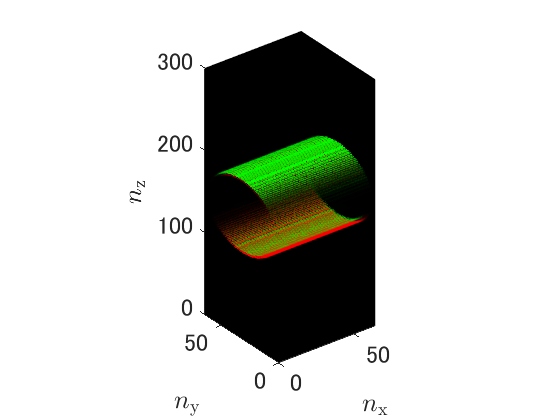

% Source
hfig = figure;
voldata = rSrc;
fcn_volviewer_(hfig,voldata,agamma);
drawnow
exportgraphics(hfig,rfigname(isubfig),"Resolution",300);

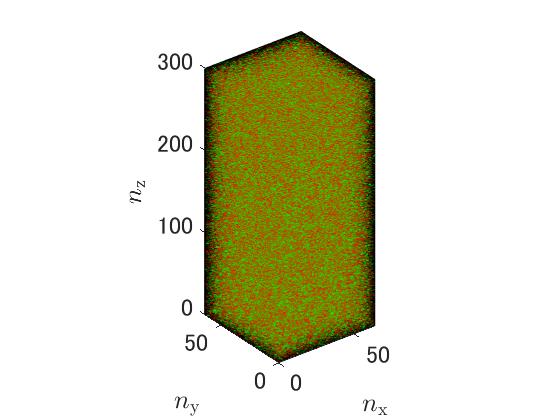

isubfig = isubfig+1;
close(hfig)

% Observation
hfig = figure;
voldata = vObs;
fcn_volviewer_(hfig,voldata,agamma);
drawnow
exportgraphics(hfig,rfigname(isubfig),"Resolution",300);




isubfig = isubfig+1;
close(hfig)

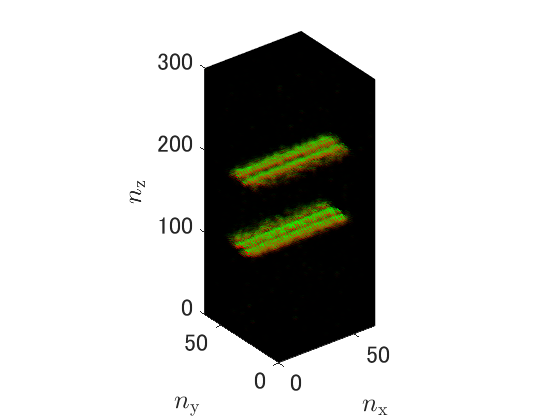


% Restoration
hfig = figure;
voldata = rEst;
fcn_volviewer_(hfig,voldata,agamma);
drawnow
exportgraphics(hfig,rfigname(isubfig),"Resolution",300);

isubfig = isubfig+1;
close(hfig)

## Functions for visualization

function fcn_stftview_(hfig,array3d,signalname,config)
win = config.win;
len = config.len;
obsz = config.obsz;
div = config.div;
[szy,szx,szz]= size(array3d);
figure(hfig)
stft(squeeze(array3d(floor(szy/2),floor(szx/2),:)),'Window',win,'OverlapLength',len-obsz/div,'FFTLength',2048);
ylabel("Normalized Frequency ($\times\pi$ radians/sample)","Interpreter","latex")
xlabel("$n_\mathrm{z}$", "Interpreter","latex")
title("Short-Time Fourier Transform ("+signalname+")")
caxis([-30 30])
yticks(-1:0.5:1)
%
hcb = hfig.Children(1);
hcb.Label.String = 'Magnitude (dB)';
hcb.FontSize = 14;
hax = hfig.Children(2);
hax.FontSize = 14;
end

function fcn_waveview_(hfig,v1,v2,signalnames,ylb)
    zline1 = squeeze(v1(floor(end/2),floor(end/2),:));
    hplt1 = plot(zline1);
    hplt1.LineWidth = 1;
    xlabel("$n_\mathrm{z}$","Interpreter","latex")
    ylabel(ylb,"Interpreter","latex")
    ymax = 1;
    ymin = -1;
    axis([0 size(v1,3) ymin ymax])
    ax = hplt1.Parent;
    ax.DataAspectRatio = [81 1 1];
    ax.FontSize = 12;
    hold on
    %
    zline2 = squeeze(v2(floor(end/2),floor(end/2),:));
    hplt2 = plot(zline2);
    hplt2.LineWidth = 1;
    % Popout
    % - Reference
    % https://jp.mathworks.com/matlabcentral/fileexchange/30556-popout
    fgauss2 = fit((1:length(zline2)).',zline2(:),'gauss2');
    [b,idx] = min([fgauss2.b1,fgauss2.b2]);
    sgm = (idx==1)*sqrt(fgauss2.c1/2) + (idx==2)*sqrt(fgauss2.c2/2);
    xmin = floor(b-6*sgm);
    xmax = ceil(b+6*sgm);
    rectangle('Position',[xmin,ymin,xmax-xmin,ymax-ymin], 'linewidth', 1);
    line([xmax,201],[ymax,-0.09],"Color","black","LineWidth",1) % TODO
    line([xmax,201],[ymin,-0.91],"Color","black","LineWidth",1) % TODO
    %
    pos0 = ax.Position;
    axpp = copyobj(ax,hfig);
    ppleft = (pos0(1)+pos0(3)*(2/3));
    ppbottom =  (pos0(2)+pos0(4)*(9/50));
    ppwidth = pos0(3)/3;
    ppheight = pos0(4)*(3/10);
    axpp.Position = [ ppleft ppbottom ppwidth ppheight ];
    axpp.XLim = [xmin xmax];
    axpp.XLabel.String = "";
    axpp.YLabel.String = "";
    axpp.DataAspectRatio = [9 1 1];
    axpp.XTick = [];
    axpp.YTick = [];
    axpp.LineWidth = 1;
    axpp.Color = [1 1 1];
    % Legend
    hlgnd = legend(ax,signalnames);
    hlgnd.FontSize = 9;
    hlgnd.FontName = "Arial Narrow";
    hold off
    %

end


function fcn_volviewer_(hfig,voldata,agamma)
    if nargin < 3
        agamma = 1;
    end
    figure(hfig)
    bvol = zeros(size(voldata));
    gvol = voldata>0;
    rvol = voldata<0;
    cdata = cat(4,rvol,gvol,bvol);
    alpha  = (abs(voldata)/max(abs(voldata(:)))).^agamma;
    hvol = support.vol3d('CData',cdata,'Alpha',alpha);
    view(3)
    ax = hvol.parent;
    ax.XLim = [0 size(voldata,1)];
    ax.YLim = [0 size(voldata,2)];
    ax.ZLim = [0 size(voldata,3)];
    ax.Color = [0 0 0];
    ax.DataAspectRatio = [1 1 2];
    ax.XTick = [0 5]*10;
    ax.YTick = [0 5]*10;
    ax.ZTick = (0:3)*1e2;
    ax.XLabel.String = "$n_\mathrm{x}$";
    ax.XLabel.Interpreter = "latex";
    ax.YLabel.String = "$n_\mathrm{y}$";
    ax.YLabel.Interpreter = "latex";
    ax.ZLabel.String = "$n_\mathrm{z}$";
    ax.ZLabel.Interpreter = "latex";
    ax.FontSize = 18;
end

function [hslice, hplot] = fcn_yzsliceplot_(hfig,v,range,tstr,ylb,sgamma)
if nargin < 6
    sgamma = 1;
end
figure(hfig)
[szy,szx,szz] = size(v);
yzslice = squeeze(v(:,floor(szx/2),:));
zline = squeeze(v(floor(szy/2),floor(szx/2),:));
% Y-Z slice
subplot(2,1,1)
yzslice = (yzslice-range(1))/(range(2)-range(1));
if range(1) >= 0
    cmap = colormap(gray(256)).^sgamma;
else
    cmap = zeros(256,3);
    cmap(:,1) = ([127:-1:0 zeros(1,128)].'/127).^sgamma; % R
    cmap(:,2) = ([zeros(1,128)    0:127].'/127).^sgamma; % G
end
hslice = imshow(yzslice);
ax = hslice.Parent;
ax.Colormap = cmap;
ax.DataAspectRatioMode = "manual";
ax.DataAspectRatio = [2 1 1];
ax.YLabel.String = "$n_\mathrm{y}$";
ax.YLabel.Interpreter = "latex";
ax.XLabel.String = "$n_\mathrm{z}$";
ax.XLabel.Interpreter = "latex";
ax.FontSize = 14;
ax.XLabel.Position(2) = szy;
pos0 = ax.Position;
ax.Title.String = tstr;
% Z plot
subplot(2,1,2)
hplot = plot(1:szz,zline);
ax = hplot.Parent;
ax.YLabel.String = "Intensity";
ax.XLabel.String = "$n_\mathrm{z}$";
ax.XLabel.Interpreter = "latex";
ax.FontSize = 14;
ax.YLim = range;
ax.YTick = linspace(range(1),range(2),3);
ax.XTick = 0:50:300;
ax.DataAspectRatioMode = "manual";
ax.DataAspectRatio = [round(600/(range(2)-range(1))) 10 1];
ax.Position(1) = pos0(1)+.088; % left
ax.Position(2) = pos0(2)-.32; % bottom
ax.Position(3) = pos0(3)-.177; % width
ax.XLabel.Position(2) = range(1)-(range(2)-range(1))*(5/12);
ax.YLabel.String = ylb;
ax.YLabel.Interpreter = "latex";
end
